# **WM9QE: Applied Statistics for Artificial Intelligence**

**Applying Inferential Statistics: Normality, Hypothesis Testing & Parametric Test (Extra Examples)**

In this section, we look into more examples. Full detail of the lectures and examples are availabe on the Moodle page here [Section: Week Two | WM9QE:Applied Statistics for Artificial Intelligence | Moodle@Warwick](https://moodle.warwick.ac.uk/course/section.php?id=621562).

# **Extra Example 1. 1-Sample z-test**

A car manufacturer produces a model with an average fuel efficiency of 15 km/L. A new fuel injection system has been developed, and engineers claim that it **increases** the average fuel efficiency. We want to statistically test whether the new system results in a significant increase in mean fuel efficiency.

**Hypotheses**: 

- H0: μ ≤ 15 (no improvement or worse) 

- H1: μ > 15 (mean efficiency has increased)

This is a **one-tailed right-sided** Z-test.

In applied AI or predictive analytics, such statistical validation is crucial when evaluating system upgrades or algorithmic improvements, we need to prove that the new system performs significantly better and that any observed improvement is not due to random variation.

clear; clc; close all;

**Step 1: Define known parameters**

mu0   = 15;      % hypothesized population mean (old system)
sigma = 1.2;     % known population standard deviation (km/L)
n     = 35;      % sample size (new system test drives)
xbar  = 15.4;    % observed sample mean from new system
alpha = 0.05;    % significance level (5%)


**Step 2: Compute Z statistic**

Z = (xbar - mu0) / (sigma / sqrt(n))

Z =           1.97202659436654


**Step 3: Compute one-tailed p-value (right tail)**

p_value = 1 - normcdf(Z)

p_value =         0.0243032853367178


**Step 4: Find critical Z for right-tailed test**

z_crit = norminv(1 - alpha)   % e.g., 1.645 for α=0.05

z_crit =           1.64485362695147


**Step 5: Decision rule**

if Z > z_crit
    decision = "Reject H0";
else
    decision = "Fail to reject H0";
end


**Step 6: Display summary table**

Results = table(Z, p_value, z_crit, string(decision), ...
    'VariableNames', {'Z_Value','P_Value','Critical_Z','Decision'});
disp('Results of One-Tailed Z-Test for Fuel Efficiency:')

Results of One-Tailed Z-Test for Fuel Efficiency:


disp(Results)

        Z_Value              P_Value             Critical_Z        Decision  
    ________________    __________________    ________________    ___________

    1.97202659436654    0.0243032853367178    1.64485362695147    "Reject H0"



**Step 7: Visualization**

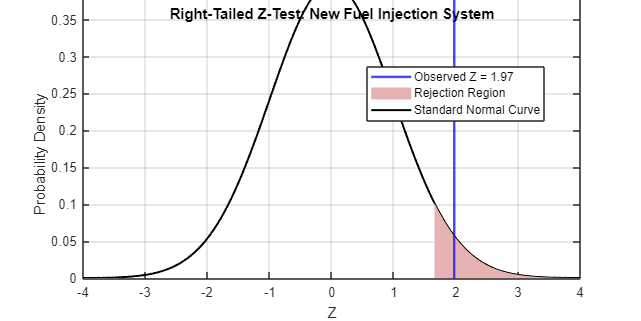

z = linspace(-4, 4, 400);
pdfz = normpdf(z, 0, 1);

figure('Color','w','Position',[100 100 800 400]);
plot(z, pdfz, 'k', 'LineWidth',1.5, 'DisplayName','Standard Normal Curve'); hold on;

% Shade rejection region (right tail)
area(z(z >= z_crit), pdfz(z >= z_crit), 'FaceColor',[0.9 0.7 0.7], 'EdgeColor','none', 'DisplayName','Rejection Region');

% Observed Z line
xline(Z, 'b', 'LineWidth',1.8, 'DisplayName', sprintf('Observed Z = %.2f', Z));

xlabel('Z'); ylabel('Probability Density');
title('Right-Tailed Z-Test: New Fuel Injection System');
legend('Location','best');
grid on;

**Step 8: Interpretation**

fprintf('\nInterpretation:\n');


Interpretation:


fprintf('Observed sample mean = %.2f km/L, expected mean = %.2f km/L\n', xbar, mu0);

Observed sample mean = 15.40 km/L, expected mean = 15.00 km/L


fprintf('Z = %.3f, p = %.4f, critical Z = %.3f (α = %.2f)\n', Z, p_value, z_crit, alpha);

Z = 1.972, p = 0.0243, critical Z = 1.645 (α = 0.05)



if Z > z_crit
    fprintf('→ Since Z > %.2f or p < %.2f, we REJECT H0.\n', z_crit, alpha);
    fprintf('There is significant evidence that the new system increases fuel efficiency.\n');
else
    fprintf('→ Since Z ≤ %.2f or p ≥ %.2f, we FAIL to reject H0.\n', z_crit, alpha);
    fprintf('No significant evidence that the new system improves fuel efficiency.\n');
end

→ Since Z > 1.64 or p < 0.05, we REJECT H0.


There is significant evidence that the new system increases fuel efficiency.


**Step 9: Applied AI/Engineering Relevance**

In AI and data-driven optimization, this is similar to testing whether a new model, algorithm, or control system significantly improves a KPI. Statistical validation ensures that observed performance improvements (e.g., better accuracy or efficiency) are *real* and not due to chance.

# **Extra Example 2. 1-Sample t-Test**

A toy company expects demand for a new toy to be $\mu =40$ units per retail outlet. Before deciding production levels, they sample 25 outlets and find: Sample mean $\left(\textrm{\=x}\right)=37\ldotp 4$  units Sample standard deviation $\left(s\right)=11\ldotp 79$ units. They want to test: 

- $H_0$: $\mu =40$ (mean demand equals the expected value) 

- $H_1$: $\mu \not= 40$ (mean demand differs from the expected value)

This is a two-tailed **t**-test with $\alpha =0\ldotp 05$. If $H_0$ cannot be rejected, they will continue using 40 units in planning. Otherwise, they must re-evaluate production levels.

**AI Relevance:** The same logic applies to testing whether an AI model’s **average forecast** (e.g., sales, customer conversions) significantly deviates from a target value.

clear; clc; close all;

**Step 1. Define sample information and assumptions**

mu0   = 40;        % hypothesized population mean (expected demand)
xbar  = 37.4;      % sample mean
s     = 11.79;     % sample standard deviation
n     = 25;        % sample size
alpha = 0.05;      % significance level

df    = n - 1;                 % degrees of freedom
SE    = s / sqrt(n);           % standard error of the mean
t_calc = (xbar - mu0) / SE;    % test statistic
t_crit = tinv(1 - alpha/2, df); % two-tailed critical t-value
p_value = 2 * (1 - tcdf(abs(t_calc), df)); % two-tailed p-value
CI = [xbar - t_crit*SE, xbar + t_crit*SE]; % 95% confidence interval

fprintf('\n--- Step 1: Descriptive Summary ---\n');


--- Step 1: Descriptive Summary ---


fprintf('Sample size (n)        = %d\n', n);

Sample size (n)        = 25


fprintf('Sample mean (x̄)        = %.2f\n', xbar);

Sample mean (x̄)        = 37.40


fprintf('Sample std deviation(s) = %.2f\n', s);

Sample std deviation(s) = 11.79


fprintf('Standard Error (SE)     = %.3f\n', SE);

Standard Error (SE)     = 2.358


fprintf('Degrees of freedom (df) = %d\n', df);

Degrees of freedom (df) = 24


**Step 2. Visualizing the sample (descriptive perspective)**

Here, we simulate 25 observations to visualize the data conceptually. (In a real setting, these would come from actual sampled stores.)

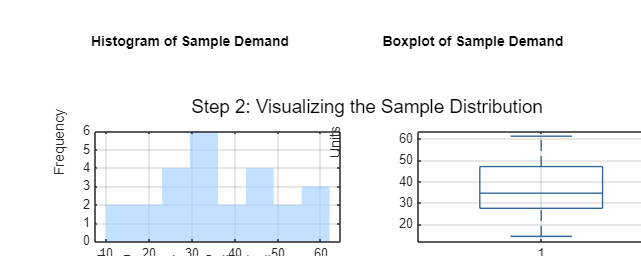

rng(1);
toy_demand_sample = normrnd(xbar, s, [n,1]);

figure('Color','w','Position',[100 100 1000 400]);
subplot(1,2,1);
histogram(toy_demand_sample, 8, 'FaceColor',[0.6 0.8 1], 'EdgeColor','none');
xlabel('Toy Demand per Outlet (units)');
ylabel('Frequency');
title('Histogram of Sample Demand');
grid on;

subplot(1,2,2);
boxplot(toy_demand_sample, 'Colors',[0.2 0.4 0.6], 'Widths',0.5);
ylabel('Units');
title('Boxplot of Sample Demand');
grid on;
sgtitle('Step 2: Visualizing the Sample Distribution');

**Step 3. Hypothesis Testing (Manual Computation)**

fprintf('\n--- Step 3: Hypothesis Test (Manual) ---\n');


--- Step 3: Hypothesis Test (Manual) ---


fprintf('t-statistic = %.3f\n', t_calc);

t-statistic = -1.103


fprintf('t-critical (±tα/2, df=%d) = ±%.3f\n', df, t_crit);

t-critical (±tα/2, df=24) = ±2.064


fprintf('Two-tailed p-value = %.4f\n', p_value);

Two-tailed p-value = 0.2811



% Decision rule
if abs(t_calc) > t_crit
    decision = "Reject H₀ (mean demand differs from 40)";
else
    decision = "Fail to reject H₀ (keep 40-unit planning estimate)";
end

% Display summary table
Results = table(n, xbar, s, df, SE, t_calc, t_crit, p_value, CI(1), CI(2), string(decision), ...
    'VariableNames', {'n','SampleMean','SampleStd','df','SE','t_calc','t_crit','p_value','CI_Lower','CI_Upper','Decision'});
disp('--- One-Sample t-Test Results ---')

--- One-Sample t-Test Results ---


disp(Results)

    n     SampleMean    SampleStd    df     SE           t_calc               t_crit              p_value             CI_Lower            CI_Upper                              Decision                      
    __    __________    _________    __    _____    _________________    ________________    _________________    ________________    ________________    ____________________________________________________

    25       37.4         11.79      24    2.358    -1.10262934690416    2.06389856162803    0.281122641145416    32.5333271916811    42.2666728083189    "Fail to reject H₀ (keep 40-unit planning estimate)"



**Step 4. Visualize the Test on the t-Distribution**

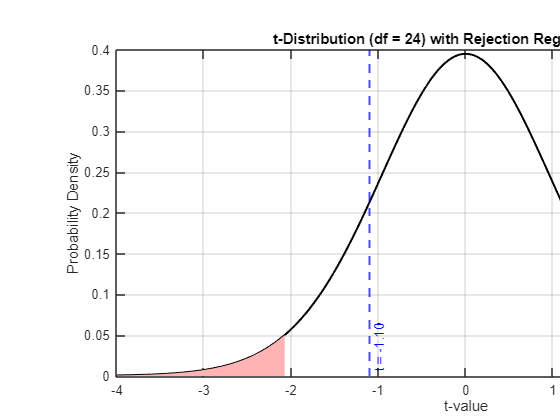

x = linspace(-4,4,400);
pdf_t = tpdf(x, df);

figure('Color','w','Position',[100 100 900 400]);
plot(x, pdf_t, 'k', 'LineWidth',1.5); hold on; grid on;

% Shade rejection regions (both tails)
area(x(x < -t_crit), pdf_t(x < -t_crit), 'FaceColor',[1 0.7 0.7], 'EdgeColor','none');
area(x(x >  t_crit), pdf_t(x >  t_crit), 'FaceColor',[1 0.7 0.7], 'EdgeColor','none');

% Mark observed t-value
xline(t_calc, '--b', sprintf('t = %.2f', t_calc), 'LineWidth',1.5, 'LabelVerticalAlignment','bottom');

xlabel('t-value');
ylabel('Probability Density');
title(sprintf('t-Distribution (df = %d) with Rejection Regions (α = %.2f)', df, alpha));
legend('t-distribution','Rejection region (left)','Rejection region (right)','Observed t','Location','best');
hold off;

**Step 5. Confidence Interval and Interpretation**

fprintf('\n--- Step 4: Confidence Interval & Decision ---\n');


--- Step 4: Confidence Interval & Decision ---


fprintf('95%% Confidence Interval for μ: [%.2f, %.2f]\n', CI(1), CI(2));

95% Confidence Interval for μ: [32.53, 42.27]



if abs(t_calc) > t_crit
    fprintf('Decision: Reject H₀ → mean demand significantly differs from 40 units.\n');
    fprintf('Business Action: Re-evaluate production planning.\n');
else
    fprintf('Decision: Fail to reject H₀ → insufficient evidence that mean differs from 40.\n');
    fprintf('Business Action: Continue planning at 40 units per retail outlet.\n');
end

Decision: Fail to reject H₀ → insufficient evidence that mean differs from 40.


Business Action: Continue planning at 40 units per retail outlet.


**Step 6. Key Learnings and AI Relevance**

fprintf('\n--- Step 5: Summary & AI Relevance ---\n');


--- Step 5: Summary & AI Relevance ---


fprintf('✔ The one-sample t-test checks if the sample mean differs from a hypothesized population mean.\n');

✔ The one-sample t-test checks if the sample mean differs from a hypothesized population mean.


fprintf('✔ It uses the sample standard deviation (s) when population σ is unknown.\n');

✔ It uses the sample standard deviation (s) when population σ is unknown.


fprintf('✔ Here, t(%.0f)=%.2f, p=%.4f → Decision: %s\n', df, t_calc, p_value, decision);

✔ Here, t(24)=-1.10, p=0.2811 → Decision: Fail to reject H₀ (keep 40-unit planning estimate)


fprintf('✔ 95%% Confidence Interval: [%.2f, %.2f]\n', CI(1), CI(2));

✔ 95% Confidence Interval: [32.53, 42.27]


fprintf('\n💡 In AI and Data Science:\n');


💡 In AI and Data Science:


fprintf('- Similar t-tests assess whether a model’s average forecast, accuracy, or latency differs from a target.\n');

- Similar t-tests assess whether a model’s average forecast, accuracy, or latency differs from a target.


fprintf('- Understanding sampling uncertainty helps prevent over-reacting to random variation in metrics.\n');

- Understanding sampling uncertainty helps prevent over-reacting to random variation in metrics.


fprintf('- For small n (limited experiments or datasets), the t-test is more reliable than the z-test.\n');

- For small n (limited experiments or datasets), the t-test is more reliable than the z-test.


# **Extra Example 3. ****1-Sample ****t-Test**

Context: A machine is designed to fill packets with 15 ounces of dried fruit. To test whether the machine is accurate, 20 packets are randomly selected, and their actual weights (in ounces) are recorded.

We want to test: H0: μ = 15 (machine is accurate on average) H1: μ ≠ 15 (machine is NOT accurate)

We will use a one-sample t-test at α = 0.05 significance level. -------------------------------------------------------------------------

clear; clc; close all;

% --- Step 1: Sample data ---
weights = [15.2 15.3 15.1 15.7 15.3 14.3 14.4 15.5 15.4 15.2 ...
           15.0 15.1 14.3 14.6 14.5 15.5 15.6 15.1 15.3 15.1];

mu0 = 15;            % Hypothesized population mean
alpha = 0.05;        % Significance level

% --- Step 2: Descriptive statistics ---
n = length(weights);             % Sample size
xbar = mean(weights);            % Sample mean
s = std(weights);                % Sample standard deviation
SE = s / sqrt(n);                % Standard Error
df = n - 1;                      % Degrees of freedom

fprintf('Sample Mean = %.3f, Standard Deviation = %.3f, n = %d\n', xbar, s, n);

Sample Mean = 15.075, Standard Deviation = 0.431, n = 20



% --- Step 3: Compute test statistic and critical values ---
t_calc = (xbar - mu0) / SE;                 % t statistic
t_crit = tinv(1 - alpha/2, df);             % Two-tailed critical t value
p_value = 2 * (1 - tcdf(abs(t_calc), df));  % Two-tailed p-value

% --- Step 4: Confidence interval for the mean ---
CI = [xbar - t_crit * SE, xbar + t_crit * SE];

% --- Step 5: Decision ---
if abs(t_calc) > t_crit
    decision = "Reject H0 (mean weight significantly differs from 15 oz)";
else
    decision = "Fail to reject H0 (machine appears accurate)";
end

% --- Step 6: Display results in table form ---
Results = table(n, xbar, s, df, SE, t_calc, t_crit, p_value, CI(1), CI(2), string(decision), ...
    'VariableNames', {'n','SampleMean','SampleStd','df','SE','t_calc','t_crit','p_value','CI_Lower','CI_Upper','Decision'});
disp('--- One-Sample t-Test Results: Dried Fruit Machine ---')

--- One-Sample t-Test Results: Dried Fruit Machine ---


disp(Results)

    n     SampleMean        SampleStd        df            SE                 t_calc               t_crit              p_value            CI_Lower           CI_Upper                           Decision                   
    __    __________    _________________    __    __________________    _________________    ________________    _________________    _______________    _______________    ______________________________________________

    20      15.075      0.431490684170951    19    0.0964842501464139    0.777328941108911    2.09302405440831    0.446535945043012    14.873056143572    15.276943856428    "Fail to rej

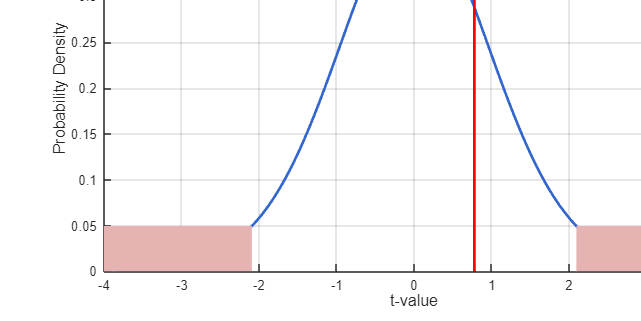


% --- Step 7: Visualize the t-distribution ---
t_vals = linspace(-4,4,400);
pdf_vals = tpdf(t_vals, df);

figure('Color','w','Position',[100 100 800 450])
plot(t_vals, pdf_vals, 'LineWidth',2, 'Color',[0.2 0.4 0.8]);
hold on;

% Shade rejection regions
fill([-4 -t_crit -t_crit -4], [0 0 tpdf(-t_crit,df) tpdf(-t_crit,df)], [0.9 0.7 0.7], 'EdgeColor','none');
fill([t_crit 4 4 t_crit], [tpdf(t_crit,df) tpdf(t_crit,df) 0 0], [0.9 0.7 0.7], 'EdgeColor','none');

% Plot calculated t statistic
line([t_calc t_calc], [0 max(pdf_vals)*0.9], 'Color','r', 'LineWidth',2);
text(t_calc+0.1, max(pdf_vals)*0.8, sprintf('t_{calc} = %.2f',t_calc),'Color','r','FontSize',12);

% Add labels
title('t-Distribution: One-Sample t-Test for Machine Accuracy','FontSize',14,'FontWeight','bold');
xlabel('t-value','FontSize',12);
ylabel('Probability Density','FontSize',12);
legend('t-distribution','Rejection Region (α/2)','t_{calc}','Location','northwest');
grid on;
hold off;


% --- Step 8: Interpretation ---
fprintf('\nInterpretation:\n');


Interpretation:


fprintf('t(%.0f) = %.2f, p = %.4f, α = %.2f\n', df, t_calc, p_value, alpha);

t(19) = 0.78, p = 0.4465, α = 0.05


if abs(t_calc) > t_crit
    fprintf('→ Reject H0: Evidence suggests the machine does not fill 15 oz on average.\n');
else
    fprintf('→ Fail to reject H0: No significant evidence of deviation from 15 oz target.\n');
end

→ Fail to reject H0: No significant evidence of deviation from 15 oz target.


fprintf('95%% Confidence Interval for μ: [%.3f, %.3f]\n', CI(1), CI(2));

95% Confidence Interval for μ: [14.873, 15.277]


# **Extr****a** **Example 4. F-Test**

We compare the variability of maturities (years to maturity) for AAA-rated bonds and CCC-rated bonds. Given summary statistics (no raw data): n1 = 17 (AAA sample size) n2 = 11 (CCC sample size) s1² = 123.35 (AAA sample variance) s2² = 8.02 (CCC sample variance)

**Hypotheses** (Two-Tailed): 

- H₀: σ₁² = σ₂² → The population variances are equal 

- H₁: σ₁² ≠ σ₂² → The population variances differ

Significance Level: α = 0.02 (2%)

**Learning Objectives:**

-     Compute an F statistic from two sample variances.

-     Obtain one-/two-tailed p-values and critical values from the F distribution.

-     Make a hypothesis decision at a chosen alpha and interpret it

**Step 0. Initialize Workspace**

clear; clc; close all; 
% clear       → removes all variables to start fresh
% clc         → clears the command window
% close all   → closes all open figure windows

**Step 1. Problem setup (parameters)**

Input sample sizes and sample variances

n1   = 17;         % AAA sample size
n2   = 11;         % CCC sample size
s2_1 = 123.35;     % sample variance for AAA group
s2_2 = 8.02;       % sample variance for CCC group
alpha = 0.02;      % significance level (two-tailed, 2%)

% Degrees of freedom for each sample
df1 = n1 - 1;
df2 = n2 - 1;

% Compute the F statistic:
% F = variance₁ / variance₂
% (order matters: the group with larger variance is often placed on top)
Fcalc = s2_1 / s2_2;

fprintf('Inputs:\n');

Inputs:


fprintf('  n1 = %d (AAA), n2 = %d (CCC)\n', n1, n2);

  n1 = 17 (AAA), n2 = 11 (CCC)


fprintf('  s1² = %.2f (AAA), s2² = %.2f (CCC)\n', s2_1, s2_2);

  s1² = 123.35 (AAA), s2² = 8.02 (CCC)


fprintf('Degrees of freedom: df1 = %d, df2 = %d\n', df1, df2);

Degrees of freedom: df1 = 16, df2 = 10


fprintf('Computed F statistic (AAA/CCC) = %.3f\n\n', Fcalc);

Computed F statistic (AAA/CCC) = 15.380



**Step 2. Compute critical values and p-values**

Two-tailed test: α = 0.02 → α/2 = 0.01 in each tail Compute critical boundaries of rejection regions

Fcrit_low  = finv(alpha/2, df1, df2);       % lower 1% quantile
Fcrit_high = finv(1 - alpha/2, df1, df2);   % upper 99% quantile

% Compute cumulative probabilities for the calculated F value
%   fcdf(x,df1,df2) = P(F ≤ x)
p_left  = fcdf(Fcalc, df1, df2);      % left-tail probability
p_right = 1 - p_left;                 % right-tail probability
p_two   = 2 * min(p_left, p_right);   % two-tailed p-value definition

fprintf('Critical values (two-tailed, α = %.2f):\n', alpha);

Critical values (two-tailed, α = 0.02):


fprintf('  Fcrit_low  = finv(%.3f, %d, %d)  = %.3f\n', alpha/2, df1, df2, Fcrit_low);

  Fcrit_low  = finv(0.010, 16, 10)  = 0.271


fprintf('  Fcrit_high = finv(%.3f, %d, %d) = %.3f\n\n', 1 - alpha/2, df1, df2, Fcrit_high);

  Fcrit_high = finv(0.990, 16, 10) = 4.520




fprintf('p-values:\n');

p-values:


fprintf('  Left-tail  p_left  = P(F ≤ Fcalc) = %.4g\n', p_left);

  Left-tail  p_left  = P(F ≤ Fcalc) = 0.9999


fprintf('  Right-tail p_right = P(F ≥ Fcalc) = %.4g\n', p_right);

  Right-tail p_right = P(F ≥ Fcalc) = 5.709e-05


fprintf('  Two-tailed p_two   = 2 × min(p_left, p_right) = %.4g\n\n', p_two);

  Two-tailed p_two   = 2 × min(p_left, p_right) = 0.0001142



**Step 3. Decision Logic**

Decision rule: Reject H₀ if Fcalc < Fcrit_low OR Fcalc > Fcrit_high

if (Fcalc < Fcrit_low) || (Fcalc > Fcrit_high)
    decision = 'Reject H₀ → Strong evidence that variances differ (AAA vs CCC).';
else
    decision = 'Fail to reject H₀ → No significant evidence that variances differ.';
end

fprintf('Decision at α = %.2f: %s\n\n', alpha, decision);

Decision at α = 0.02: Reject H₀ → Strong evidence that variances differ (AAA vs CCC).



**Step 4. Compact Summary Table**

Create a simple tabular summary.

Row = {'n'; 'df'; 'SampleVariance'; 'Fcalc'; ...
       'Fcrit_low (α/2)'; 'Fcrit_high (1−α/2)'; ...
       'p_left'; 'p_right'; 'p_two'; 'Decision'};

AAA_col = {n1; df1; s2_1; Fcalc; Fcrit_low; Fcrit_high; p_left; p_right; p_two; decision};
CCC_col = {n2; df2; s2_2; NaN; NaN; NaN; NaN; NaN; NaN; ''};

Summary = table(Row, AAA_col, CCC_col, 'VariableNames', {'Quantity','AAA','CCC'});
disp(Summary);

           Quantity                                           AAA                                        CCC    
    ______________________    ____________________________________________________________________    __________

    {'n'                 }    {[                                                              17]}    {[    11]}
    {'df'                }    {[                                                              16]}    {[    10]}
    {'SampleVariance'    }    {[                                                          123.35]}    {[  8.02]}
    {'Fcalc'             }    {[                                                15.3802992518703]}    {[   NaN]}
    {'Fcrit_low (α/2)'   }    {[                                               0.270934321659727]}    {[   NaN]}
    {'Fcrit_high (1−α/2)'}    {[                                                4.52044821618009]}    {[  

**Step 5. F distribution Plot with Rejection Regions (Optional)**

Visualize both tails of the F distribution and show where Fcalc falls. Shaded regions represent rejection zones.

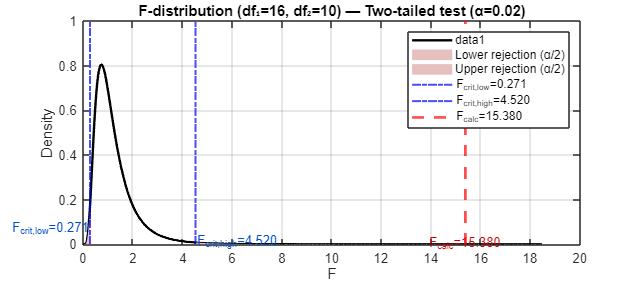

% Define plotting range wide enough to cover critical regions
x = linspace(0, max(max(5, Fcrit_high*1.5), Fcalc*1.2), 1200);
y = fpdf(x, df1, df2); % F-distribution PDF

figure('Color','w','Position',[120 120 1000 440])
plot(x, y, 'k-', 'LineWidth',1.8); grid on; hold on
title(sprintf('F-distribution (df₁=%d, df₂=%d) — Two-tailed test (α=%.2f)', df1, df2, alpha));
xlabel('F'); ylabel('Density');

% Shade the left-tail rejection region [0, Fcrit_low]
xL = x(x <= Fcrit_low); yL = y(x <= Fcrit_low);
fill([xL fliplr(xL)], [yL zeros(size(yL))], [0.9 0.75 0.75], ...
     'EdgeColor','none', 'DisplayName','Lower rejection (α/2)');

% Shade the right-tail rejection region [Fcrit_high, ∞)
xU = x(x >= Fcrit_high); yU = y(x >= Fcrit_high);
fill([xU fliplr(xU)], [yU zeros(size(yU))], [0.9 0.75 0.75], ...
     'EdgeColor','none', 'DisplayName','Upper rejection (α/2)');

% Add vertical reference lines
xline(Fcrit_low,  'b-.', 'LineWidth',1.5, 'DisplayName',sprintf('F_{crit,low}=%.3f',Fcrit_low));
xline(Fcrit_high, 'b-.', 'LineWidth',1.5, 'DisplayName',sprintf('F_{crit,high}=%.3f',Fcrit_high));
xline(Fcalc,      'r--', 'LineWidth',2.0, 'DisplayName',sprintf('F_{calc}=%.3f',Fcalc));

% Annotate values for clarity
yl = interp1(x, y, Fcrit_low);
yr = interp1(x, y, Fcrit_high);
yc = interp1(x, y, Fcalc);
text(Fcrit_low,  yl*0.4, sprintf('F_{crit,low}=%.3f',Fcrit_low), 'HorizontalAlignment','right', 'Color',[0 0.3 0.8]);
text(Fcrit_high, yr*1.1, sprintf('F_{crit,high}=%.3f',Fcrit_high), 'HorizontalAlignment','left', 'Color',[0 0.3 0.8]);
text(Fcalc,      yc*1.15, sprintf('F_{calc}=%.3f',Fcalc), 'HorizontalAlignment','center', 'Color',[0.8 0 0]);
legend('Location','northeast'); hold off;

**Step 6. Instructor-Style Interpretation Notes**

fprintf('INSTRUCTOR NOTES:\n');

INSTRUCTOR NOTES:


fprintf('- Fcalc = %.3f is far larger than 1, indicating AAA variance >> CCC variance.\n', Fcalc);

- Fcalc = 15.380 is far larger than 1, indicating AAA variance >> CCC variance.


fprintf('- p_right is extremely small, so the two-tailed p-value is also small.\n');

- p_right is extremely small, so the two-tailed p-value is also small.


fprintf('- Because p_two < α = %.2f, we reject H₀.\n', alpha);

- Because p_two < α = 0.02, we reject H₀.


fprintf('- Interpretation: At the 2%% significance level, there is strong evidence\n');

- Interpretation: At the 2% significance level, there is strong evidence


fprintf('  that the variability of maturities differs between AAA and CCC bonds.\n');

  that the variability of maturities differs between AAA and CCC bonds.


fprintf('  Specifically, AAA-rated bonds show far greater variability.\n');

  Specifically, AAA-rated bonds show far greater variability.


**Summary**

- The **F-test** checks whether two groups differ **in variability**, not in their means.

- If F = 1, the variances are identical.

- A **large F** means the numerator group (AAA) has much more variability.

- Here, AAA’s sample variance (123.35) is vastly higher than CCC’s (8.02), so F ≈ 15.38, **far beyond** what random sampling would explain.

- Hence, **we reject H₀**: AAA and CCC bond maturity variances are significantly different.

# **Extra Example 5. 2-Sample t-Test**

 A sporting goods manager suspects that Monday sales might differ from Saturday sales, perhaps Mondays are busier. We want to statistically test whether the average Monday sales are **different** from Saturday sales.

We use a **two-sample t-test** assuming: 

- Two independent samples (Monday vs Saturday) 

- Approximately normal distributions 

- Equal population variances (we will pool them)

Hypotheses (Two-Tailed) 

- H₀: μ₁ = μ₂ → No mean difference between Monday and Saturday 

- H₁: μ₁ ≠ μ₂ → Mean sales differ between Monday and Saturday

Significance level: α = 0.05 (5%)

**Step 0. Initialize Workspace**

clear; clc; close all; format long g;
% clear       → removes all variables to start fresh
% clc         → clears the command window
% close all   → closes all open figure windows
% format long g → displays numerical results with higher precision

**Step 1. Input Summary Data**

Instead of raw sales data, we are provided with **summary statistics**: 

- Sample mean (x̄) 

- Sample standard deviation (s) 

- Sample size (n)

% Monday group (Group 1)
xbar1 = 1078;     % mean Monday sales (€ or units)
s1    = 633;      % standard deviation of Monday sales
n1    = 25;       % sample size for Monday

% Saturday group (Group 2)
xbar2 = 908.2;    % mean Saturday sales (€ or units)
s2    = 469.8;    % standard deviation of Saturday sales
n2    = 25;       % sample size for Saturday

**Step 2. Descriptive Summary**

Let's present a quick descriptive summary table. This helps visualize differences in sample means and variability.

Desc = table([xbar1; s1; n1], [xbar2; s2; n2], ...
    'VariableNames', {'Monday','Saturday'}, ...
    'RowNames', {'Mean','StdDev (sample)','Count'});
disp('Descriptive Summary (Given):');

Descriptive Summary (Given):


disp(Desc);

                       Monday    Saturday
                       ______    ________

    Mean                1078      908.2  
    StdDev (sample)      633      469.8  
    Count                 25         25  



**Step 3. Visualization Theoretical Normal Curves**

We’ll visualize both groups in overlayed normal distributions using the sample means and SDs

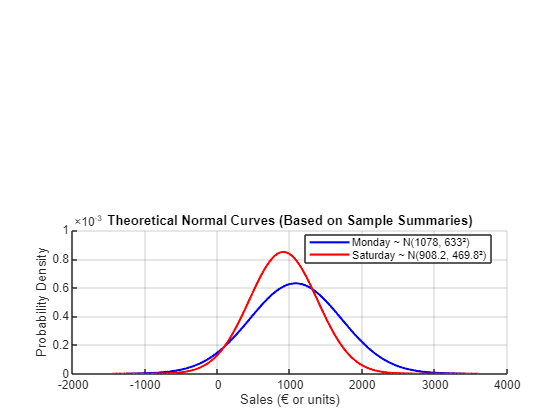

figure;

% ---- Theoretical Normal Curves ----
subplot(2,1,2); hold on;

% Define x-range for smooth normal curves
xmin = min([xbar2 - 4*s2, xbar1 - 4*s1]);
xmax = max([xbar2 + 4*s2, xbar1 + 4*s1]);
x = linspace(xmin, xmax, 600);

% Compute probability density for both groups
plot(x, normpdf(x, xbar1, s1), 'b-', 'LineWidth', 1.6);
plot(x, normpdf(x, xbar2, s2), 'r-', 'LineWidth', 1.6);

title('Theoretical Normal Curves (Based on Sample Summaries)');
xlabel('Sales (€ or units)');
ylabel('Probability Density');
legend('Monday ~ N(1078, 633²)','Saturday ~ N(908.2, 469.8²)','Location','best');
grid on; hold off;

**Step 4. Test Statistic Calculation**

Since we assume **equal variances**, we use the **pooled variance formula**.

% Degrees of freedom (for equal variances)
df  = n1 + n2 - 2;

% Compute pooled variance:
%   sp² = [(n1-1)s1² + (n2-1)s2²] / (n1 + n2 - 2)
sp2 = ((n1-1)*s1^2 + (n2-1)*s2^2) / df;

% Pooled standard deviation:
sp  = sqrt(sp2);

% Standard error of the difference between two means:
%   SE = sp * √(1/n1 + 1/n2)
SE  = sp * sqrt(1/n1 + 1/n2);

% Difference in sample means:
diff_means = xbar1 - xbar2;

% t-statistic (two-sample, equal variances):
%   t = (x̄₁ - x̄₂) / SE
t_stat = diff_means / SE;

% Compute p-values and critical t-values
p_two = 2 * (1 - tcdf(abs(t_stat), df));  % two-tailed p-value
p_one = p_two / 2;                         % one-tailed p-value (if needed)

% Critical t-values for α = 0.05
tcrit_two = tinv(1 - 0.025, df);           % two-tailed (split α/2 each tail)
tcrit_one = tinv(1 - 0.05,  df);           % one-tailed (α = 0.05)

% 95% Confidence Interval for difference in means:
%   (x̄₁ - x̄₂) ± tcrit_two * SE
CI_low  = diff_means - tcrit_two * SE;
CI_high = diff_means + tcrit_two * SE;

% Display numerical results
fprintf('\n--- Step 3: Test Results ---\n');


--- Step 3: Test Results ---


fprintf('Pooled variance (sp²) = %.2f\n', sp2);

Pooled variance (sp²) = 310700.52


fprintf('Pooled SD (sp)        = %.4f\n', sp);

Pooled SD (sp)        = 557.4052


fprintf('Degrees of freedom    = %d\n', df);

Degrees of freedom    = 48


fprintf('t = %.4f\n', t_stat);

t = 1.0770


fprintf('p(two-tail) = %.4f,  p(one-tail) = %.4f\n', p_two, p_one);

p(two-tail) = 0.2869,  p(one-tail) = 0.1434


fprintf('95%% CI for (μ₁ - μ₂) = [%.1f , %.1f]\n', CI_low, CI_high);

95% CI for (μ₁ - μ₂) = [-147.2 , 486.8]


**Step 5. Visualization of the Test (Optional)**

We will plot the t-distribution with rejection regions shaded to visually understand where the computed t-statistic falls.

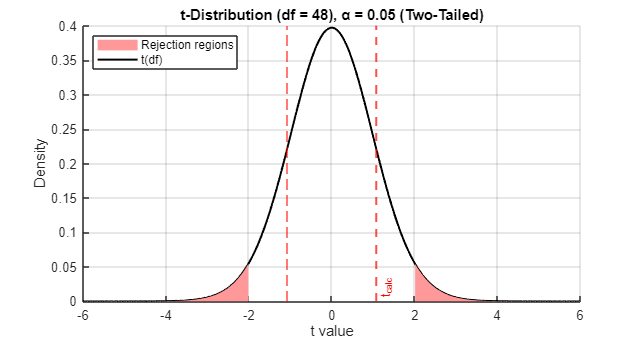

figure('Color','w','Position',[100 100 850 450]); hold on;

xx = linspace(-6,6,600);          % range of t-values
yy = tpdf(xx, df);                % density of t-distribution

plot(xx, yy, 'k-', 'LineWidth', 1.5);

% Shade both rejection regions (two tails, α = 0.05 → 0.025 each)
area(xx(xx<-tcrit_two), yy(xx<-tcrit_two), 'FaceColor',[1 0.6 0.6],'EdgeColor','none');
area(xx(xx> tcrit_two), yy(xx> tcrit_two), 'FaceColor',[1 0.6 0.6],'EdgeColor','none');

% Mark the observed t-statistic
xline(t_stat,'r--','t_{calc}','LineWidth',1.5,'LabelVerticalAlignment','bottom');
xline(-t_stat,'r--');

title(sprintf('t-Distribution (df = %d), α = 0.05 (Two-Tailed)', df));
xlabel('t value');
ylabel('Density');
legend('t(df)','Rejection regions','Location','northwest');
grid on; hold off;

**Step 6. Decision & Interpretation**

The decision rule for a two-tailed test: Reject H₀ if `t_stat` > tcrit_two OR p < α - Fail to reject H₀ otherwise

alpha = 0.05;
if p_two < alpha
    decision = "Reject H₀ → Evidence of a mean difference.";
else
    decision = "Fail to reject H₀ → No significant mean difference.";
end

fprintf('\n--- Step 5: Decision & Interpretation ---\n');


--- Step 5: Decision & Interpretation ---


fprintf('Decision: %s\n', decision);

Decision: Fail to reject H₀ → No significant mean difference.


fprintf(['Interpretation:\n' ...
         'The observed mean difference of %.1f (Monday - Saturday)\n' ...
         'gives t(%d) = %.3f and p(two-tail) = %.3f.\n' ...
         'Since p = %.3f > α = 0.05, we FAIL TO REJECT H₀.\n' ...
         'Conclusion: There is no statistically significant difference\n' ...
         'between Monday and Saturday mean sales.\n'], ...
         diff_means, df, t_stat, p_two, p_two);

Interpretation:
The observed mean difference of 169.8 (Monday - Saturday)
gives t(48) = 1.077 and p(two-tail) = 0.287.
Since p = 0.287 > α = 0.05, we FAIL TO REJECT H₀.
Conclusion: There is no statistically significant difference
between Monday and Saturday mean sales.


**Step 7. Summary of Statistical Logic**

This test checks if **Monday’s average sales differ from Saturday’s**.

- The t-statistic measures how big the difference is *relative to variability*.

- The p-value tells you how likely that difference could arise just by chance.

- If that probability (p) is small (less than α = 0.05), you call it “statistically significant.”

- In this example, **p > 0.05**, so the difference between Monday and Saturday sales isn’t statistically significant.

# **Extra Example 6. 2-Sample t-Test (Welch)**

Scenario: A poultry company tested whether a new turkey feeding programme increases the average turkey weight compared to the old programme. The two samples (new vs old) are independent and population variances are assumed to be unequal, so we use Welch’s t-test.

Hypotheses (right-tailed):

-   H0: μ1 = μ2  or  μ1 − μ2 ≤ 0   (no improvement with new feed)

-   H1: μ1 ≠ μ2  or  μ1 − μ2 > 0   (new feed increases mean weight)

Significance Level: α = 0.05 (5%)

clear; clc; close all; format long g;
% clear: removes all variables from workspace
% clc: clears command window for a clean output
% close all: closes all open figure windows
% format long g: shows more digits in numerical results (better precision)

**Step 1. Input summary data**

mean_new = 5.2;     % Mean turkey weight (kg) under NEW feed
mean_old = 4.9;     % Mean turkey weight (kg) under OLD feed
sd_new   = 0.8;     % Sample standard deviation (new feed)
sd_old   = 0.7;     % Sample standard deviation (old feed)
n_new    = 21;      % Sample size (new feed group)
n_old    = 21;      % Sample size (old feed group)

% Note: Equal sample sizes simplify the computation, but Welch’s t-test
% works even when n1 ≠ n2 and variances differ.


**Step 2. Compute test statistic (Welch formula)**

Welch's t-test does NOT assume equal variances. The test statistic measures how many standard errors apart the two means are.

% Mean difference (New - Old)
diff_mean = mean_new - mean_old;

% Standard Error (SE) of the difference using Welch’s formula:
%   SE = sqrt( (s1^2 / n1) + (s2^2 / n2) )
SE = sqrt( (sd_new^2 / n_new) + (sd_old^2 / n_old) );

% Compute the t-statistic:
%   t = (x̄1 - x̄2) / SE
t_calc = diff_mean / SE;

% --- Degrees of Freedom (Welch–Satterthwaite approximation) ---
% Welch’s test adjusts degrees of freedom to account for unequal variances.
% Formula:
%   df = [ (s1^2/n1 + s2^2/n2)^2 ] /
%        [ (s1^4 / [n1^2*(n1-1)]) + (s2^4 / [n2^2*(n2-1)]) ]
num = ( (sd_new^2 / n_new) + (sd_old^2 / n_old) )^2;
den = ( (sd_new^4 / (n_new^2 * (n_new - 1))) + (sd_old^4 / (n_old^2 * (n_old - 1))) );
df = num / den;  % approximate (non-integer) degrees of freedom

% --- Critical Value and p-Value (Right-tailed test) ---
% Since H1: μ_new > μ_old, we test only in the *right tail* of the t-distribution.
alpha = 0.05;

% t critical value for 1 - α quantile (right tail)
t_crit = tinv(1 - alpha, df);

% p-value = probability of observing t_calc or greater
p_value = 1 - tcdf(t_calc, df);

**Step 3. Display numerical results**

fprintf('\nWelch''s Two-Sample t-Test (Unequal Variances)\n');


Welch's Two-Sample t-Test (Unequal Variances)


fprintf('----------------------------------------------------\n');

----------------------------------------------------


fprintf('Group Means and Variability:\n');

Group Means and Variability:


fprintf('  Mean (New feed): %.2f kg\n', mean_new);

  Mean (New feed): 5.20 kg


fprintf('  Mean (Old feed): %.2f kg\n', mean_old);

  Mean (Old feed): 4.90 kg


fprintf('  Std. Dev (New feed): %.2f\n', sd_new);

  Std. Dev (New feed): 0.80


fprintf('  Std. Dev (Old feed): %.2f\n', sd_old);

  Std. Dev (Old feed): 0.70


fprintf('  Sample sizes: n1 = %d, n2 = %d\n', n_new, n_old);

  Sample sizes: n1 = 21, n2 = 21


fprintf('----------------------------------------------------\n');

----------------------------------------------------


fprintf('Test Statistic and Results:\n');

Test Statistic and Results:


fprintf('  Mean difference (New - Old): %.3f kg\n', diff_mean);

  Mean difference (New - Old): 0.300 kg


fprintf('  Standard Error (SE): %.4f\n', SE);

  Standard Error (SE): 0.2320


fprintf('  t_calc = %.3f\n', t_calc);

  t_calc = 1.293


fprintf('  Degrees of freedom (Welch df) = %.2f\n', df);

  Degrees of freedom (Welch df) = 39.31


fprintf('  t_crit (α = 0.05, one-tailed) = %.3f\n', t_crit);

  t_crit (α = 0.05, one-tailed) = 1.685


fprintf('  p-value (one-tailed) = %.5f\n', p_value);

  p-value (one-tailed) = 0.10173



% --- Decision Rule ---
% If t_calc > t_crit → reject H0 (significant increase)
% Otherwise → fail to reject H0
if t_calc > t_crit
    decision = "Reject H₀ → The new feeding programme significantly increases turkey weight.";
else
    decision = "Fail to reject H₀ → No significant difference found.";
end
fprintf('----------------------------------------------------\n');

----------------------------------------------------


fprintf('Decision: %s\n', decision);

Decision: Fail to reject H₀ → No significant difference found.


**Step 4. Visualize t-distribution and rejection region**

This section visually illustrates where our t_calc lies on the distribution and shows the rejection region (right tail) at α = 0.05.

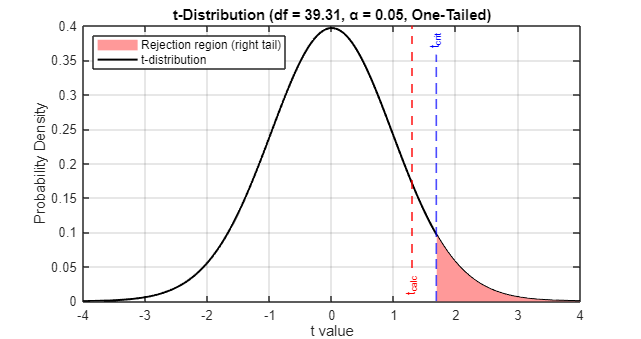


x = linspace(-4,4,500);  % x-axis range for plotting t values
y = tpdf(x, df);         % compute probability density values for t-distribution

figure('Color','w','Position',[100 100 850 450]);
plot(x, y, 'k-', 'LineWidth', 1.5); hold on;

% --- Shade rejection region (right tail where we reject H0) ---
area(x(x > t_crit), y(x > t_crit), 'FaceColor',[1 0.6 0.6], 'EdgeColor','none');

% --- Draw vertical lines for t_calc and t_crit ---
xline(t_calc, 'r--', 'LineWidth', 1.5, 'Label','t_{calc}', ...
    'LabelVerticalAlignment','bottom','LabelHorizontalAlignment','center');
xline(t_crit, 'b--', 'LineWidth', 1.2, 'Label','t_{crit}', ...
    'LabelVerticalAlignment','top','LabelHorizontalAlignment','center');

% --- Add plot labels and legend ---
title(sprintf('t-Distribution (df = %.2f, α = 0.05, One-Tailed)', df));
xlabel('t value');
ylabel('Probability Density');
legend('t-distribution','Rejection region (right tail)','Location','northwest');
grid on;
hold off;

**Step 5. Interpretation**

fprintf('\nINTERPRETATION\n');


INTERPRETATION


fprintf('----------------------------------------------------\n');

----------------------------------------------------


fprintf('At α = 0.05 (right-tailed test):\n');

At α = 0.05 (right-tailed test):


fprintf('  Calculated t = %.2f\n', t_calc);

  Calculated t = 1.29


fprintf('  Critical t = %.2f\n', t_crit);

  Critical t = 1.68


fprintf('  p-value = %.5f\n', p_value);

  p-value = 0.10173



if t_calc > t_crit
    fprintf('\n→ Since t_calc > t_crit, we REJECT H₀.\n');
    fprintf('  There is statistically significant evidence that the new feeding\n');
    fprintf('  programme increases average turkey weight compared to the old one.\n');
else
    fprintf('\n→ Since t_calc ≤ t_crit, we FAIL TO REJECT H₀.\n');
    fprintf('  We do not have sufficient evidence that the new feeding programme\n');
    fprintf('  leads to higher turkey weight.\n');
end


→ Since t_calc ≤ t_crit, we FAIL TO REJECT H₀.


  We do not have sufficient evidence that the new feeding programme


  leads to higher turkey weight.


fprintf('----------------------------------------------------\n');

----------------------------------------------------


**Step 6. Summary of Key Concepts**

- Welch’s t-test is used when two samples are independent and have unequal variances. 

- It adjusts the degrees of freedom using the Satterthwaite approximation. 

- A one-tailed test checks only for improvement (increase) in the new feed. 

- The p-value quantifies the probability of obtaining a t as large as the observed one if H0 were true (no difference in means). - If p < α or t_calc > t_crit, reject H0.

# **Extra Example 7. Paired t-Test **

**Objective**: To determine whether the NEW feeding programme changes (increases or decreases) the mean turkey weight compared to the OLD feeding programme.

Hypotheses (Two-tailed): 

- H0: μ_d = 0 → No difference in mean weight between feeding programs 

- H1: μ_d ≠ 0 → There is a significant difference in mean weight

Significance Level: α = 0.05

This script walks through all the steps of a paired t-test manually, computes test statistics, p-values, confidence intervals, and visualizes the results.

**Step 0. Initialize Environment**

clear; clc; close all; format long g;
% 'clear' removes all variables from the workspace
% 'clc' clears the command window
% 'close all' closes any open figure windows
% 'format long g' ensures more precise numeric output

**Step 1. Input Paired Data**

Each pair of values corresponds to turkeys from the same hen:  

- Old: weights under the OLD feeding programme 

- New: weights under the NEW feeding programme

Old = [8.5 9.1 7.8 8.3 8.7 9.0 8.2 7.9 8.4 9.2 8.8 8.6 8.5 8.3 8.7 8.1 8.4 8.6 9.0 8.2 8.9 8.5 8.3 8.7 8.2];
New = [9.3 9.8 8.4 9.0 9.3 9.7 8.9 8.5 9.0 10.0 9.6 9.3 9.1 8.8 9.4 8.6 8.9 9.2 9.7 8.7 9.5 9.0 8.8 9.3 8.7];

% Sample size (n) and degrees of freedom (df)
n = numel(Old);
df = n - 1;

fprintf('Sample size (n) = %d, Degrees of Freedom (df) = %d\n', n, df);

Sample size (n) = 25, Degrees of Freedom (df) = 24


**Step 2. Descriptive Statistics**

Compute basic descriptive statistics for each feeding program

Mean_old = mean(Old);
Mean_new = mean(New);
Std_old  = std(Old,0); % sample standard deviation (divides by n-1)
Std_new  = std(New,0);

fprintf('\nDESCRIPTIVE STATISTICS\n');


DESCRIPTIVE STATISTICS


fprintf('Old Feeding:  Mean = %.2f, Std = %.2f\n', Mean_old, Std_old);

Old Feeding:  Mean = 8.52, Std = 0.36


fprintf('New Feeding:  Mean = %.2f, Std = %.2f\n', Mean_new, Std_new);

New Feeding:  Mean = 9.14, Std = 0.43


**Step 3. Visualization - Boxplots and Histograms**

Visualize both datasets side-by-side to compare distribution and spread

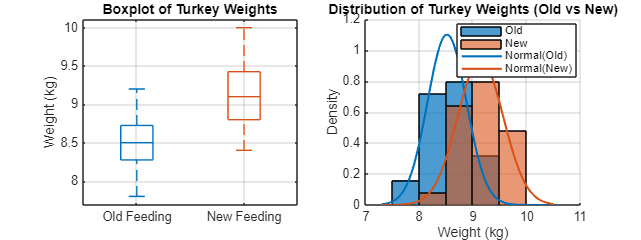

figure('Color','w','Position',[100 100 1200 450]);

% --- Boxplot ---
subplot(1,2,1);
colors = [0 0.4470 0.7410; 0.8500 0.3250 0.0980];
boxplot([Old', New'], 'Labels', {'Old Feeding','New Feeding'}, 'Colors', colors);
title('Boxplot of Turkey Weights');
ylabel('Weight (kg)');
grid on;

% --- Histogram + Normal Distribution Overlay ---
subplot(1,2,2); hold on;
histogram(Old,'Normalization','pdf','FaceColor',colors(1,:),'FaceAlpha',0.7);
histogram(New,'Normalization','pdf','FaceColor',colors(2,:),'FaceAlpha',0.6);
x = linspace(min([Old New])-0.5, max([Old New])+0.5, 400);
plot(x, normpdf(x,Mean_old,Std_old),'Color',colors(1,:),'LineWidth',1.6);
plot(x, normpdf(x,Mean_new,Std_new),'Color',colors(2,:),'LineWidth',1.6);
title('Distribution of Turkey Weights (Old vs New)');
xlabel('Weight (kg)'); ylabel('Density');
legend('Old','New','Normal(Old)','Normal(New)','Location','best');
grid on; hold off;

**Step 4. Compute Paired Differences**

Compute the difference in weights for each pair: New - Old

D = New - Old;          % individual differences
dbar = mean(D);         % mean of the differences
sd_d = std(D,0);        % standard deviation of differences
SE_d = sd_d / sqrt(n);  % standard error of the mean difference
t_stat = dbar / SE_d;   % test statistic for paired t-test

fprintf('\nPAIRED DIFFERENCES\n');


PAIRED DIFFERENCES


fprintf('Mean difference (d̄) = %.3f\n', dbar);

Mean difference (d̄) = 0.624


fprintf('Std of differences (s_d) = %.3f\n', sd_d);

Std of differences (s_d) = 0.101


fprintf('Standard Error (SE_d) = %.3f\n', SE_d);

Standard Error (SE_d) = 0.020


fprintf('t_calc = %.3f\n', t_stat);

t_calc = 30.842


**Step 5. Critical Value and p-Value (Two-tailed)**

alpha = 0.05; % significance level

% Critical t-value for two-tailed test (α/2 each side)
t_crit = tinv(1 - alpha/2, df);

% Compute p-value: two-tailed test → multiply one tail by 2
p_two = 2 * (1 - tcdf(abs(t_stat), df));

fprintf('\nTEST RESULTS (Two-Tailed)\n');


TEST RESULTS (Two-Tailed)


fprintf('t_calc = %.3f | t_crit(0.025, two-tail) = ±%.3f\n', t_stat, t_crit);

t_calc = 30.842 | t_crit(0.025, two-tail) = ±2.064


fprintf('p(two-tail) = %.5f\n', p_two);

p(two-tail) = 0.00000



% Decision rule: compare |t_calc| with t_crit
if abs(t_stat) > t_crit
    decision = 'Reject H₀ → Significant difference between feeding programmes.';
else
    decision = 'Fail to reject H₀ → No significant difference detected.';
end
fprintf('Decision: %s\n', decision);

Decision: Reject H₀ → Significant difference between feeding programmes.


**Step 6. 95% Confidence Interval for Mean Difference**

CI formula: d̄ ± t_crit * SE_d

CI_low  = dbar - t_crit * SE_d;
CI_high = dbar + t_crit * SE_d;

fprintf('95%% Confidence Interval for mean difference: [%.3f , %.3f]\n', CI_low, CI_high);

95% Confidence Interval for mean difference: [0.582 , 0.666]


Boundaries = table(CI_low, CI_high, 'VariableNames', {'Lower_Bound','Upper_Bound'});
disp('Confidence Interval (95%)'); disp(Boundaries);

Confidence Interval (95%)
       Lower_Bound          Upper_Bound   
    _________________    _________________

    0.582243229327994    0.665756770672007



**Step 7. Visualization - t-Distribution (Two-tailed Rejection Regions)**

Plot the t-distribution curve and shade rejection regions

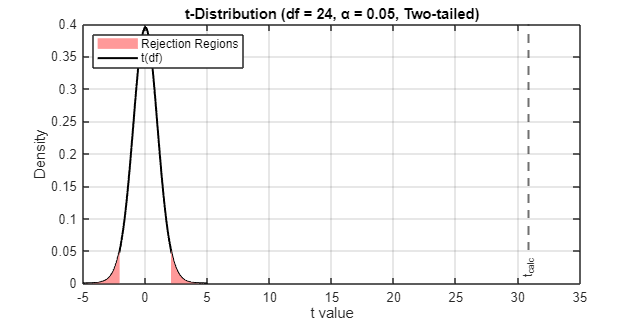

x = linspace(-5,5,400);
y = tpdf(x,df);
figure('Color','w','Position',[100 100 900 450]);
plot(x, y, 'k-', 'LineWidth', 1.5); hold on;

% Shade both tails (critical rejection regions)
area(x(x < -t_crit), y(x < -t_crit), 'FaceColor',[1 0.6 0.6], 'EdgeColor','none');
area(x(x >  t_crit), y(x >  t_crit), 'FaceColor',[1 0.6 0.6], 'EdgeColor','none');

% Mark observed t-statistic on the plot
xline(t_stat, '--', 'Color',[0.2 0.2 0.2], 'LineWidth',1.5, ...
    'Label','t_{calc}','LabelHorizontalAlignment','center','LabelVerticalAlignment','bottom');

title(sprintf('t-Distribution (df = %d, α = 0.05, Two-tailed)', df));
xlabel('t value'); ylabel('Density');
legend('t(df)','Rejection Regions','Location','northwest');
grid on; hold off;

**Step 8. Interpretation (Plain English)**

fprintf('\nINTERPRETATION\n');


INTERPRETATION


fprintf('At α = 0.05, |t_calc| = %.2f and t_crit = %.2f\n', abs(t_stat), t_crit);

At α = 0.05, |t_calc| = 30.84 and t_crit = 2.06



if abs(t_stat) > t_crit
    fprintf('→ Reject H₀: The new feeding programme significantly changes turkey weight.\n');
else
    fprintf('→ Fail to reject H₀: No significant change in turkey weight.\n');
end

→ Reject H₀: The new feeding programme significantly changes turkey weight.



fprintf('Mean difference (New - Old) = %.3f kg\n', dbar);

Mean difference (New - Old) = 0.624 kg


fprintf('95%% CI for mean difference = [%.3f , %.3f]\n', CI_low, CI_high);

95% CI for mean difference = [0.582 , 0.666]


fprintf('p(two-tail) = %.5f\n', p_two);

p(two-tail) = 0.00000


fprintf('\nConclusion: %s\n', decision);


Conclusion: Reject H₀ → Significant difference between feeding programmes.


**End of Script**

Summary: 

- We computed paired differences between two related samples (Old vs New). 

- Calculated t-statistic and p-value manually. 

- Compared with critical value at α = 0.05. - Constructed 95%% confidence interval.  

- Concluded based on statistical evidence whether to accept or reject H₀.